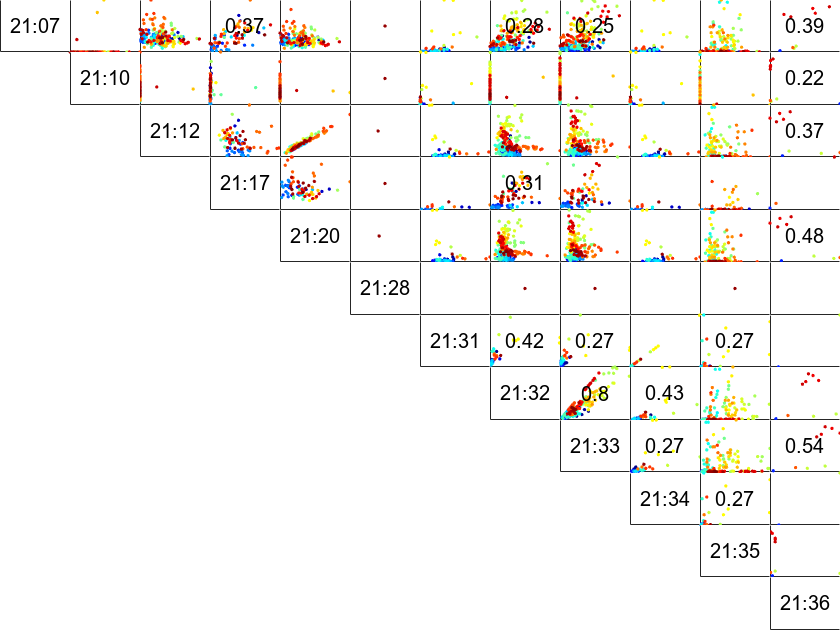

Features = DFD_FeatureTable_FreqDomain_Standard;
FeatureNames = featureNames_Freq;
SignalNames = signalNames_Freq;
lowerR2 = 0.2;
upperR2 = 0.8;
r2ReducedThreshold = 0.9;
selectedFeature = 2; % Peak Amplitude
saveFigures = true;
R2 = fnPlotSignalVsSignal(Features, lowerR2, upperR2, selectedFeature, FeatureNames, SignalNames, sensorNames); 

disp(num2str(R2, '%.2f  '));

0.00  0.01  0.04  0.37  0.02   NaN  0.18  0.28  0.25  0.18  0.03  0.39
0.00  0.00  0.00  0.00  0.00   NaN  0.01  0.01  0.01  0.01  0.00  0.22
0.00  0.00  0.00  0.03  0.94   NaN  0.07  0.02  0.00  0.07  0.00  0.37
0.00  0.00  0.00  0.00  0.02   NaN  0.03  0.31  0.19  0.03  0.05  1.00
0.00  0.00  0.00  0.00  0.00   NaN  0.03  0.00  0.00  0.03  0.00  0.48
0.00  0.00  0.00  0.00  0.00  0.00   NaN   NaN   NaN   NaN   NaN   NaN
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.42  0.27  1.00  0.27  1.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.80  0.43  0.12  0.06
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.27  0.03  0.54
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.27  1.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.00


selectedSignal = 1; % row number
selectedFeature = selectedFeature + 13;
[selectedSignalArray, selectedSignalData, numOfSelectedSignals] = fnSelectSignals(...
    selectedSignal, selectedFeature, featureArray_Standard, R2, upperR2, lowerR2, r2ReducedThreshold, true);

Sig 4 Sig 12 = 1.00
     1     4     8     9    12
     1     4     8     9


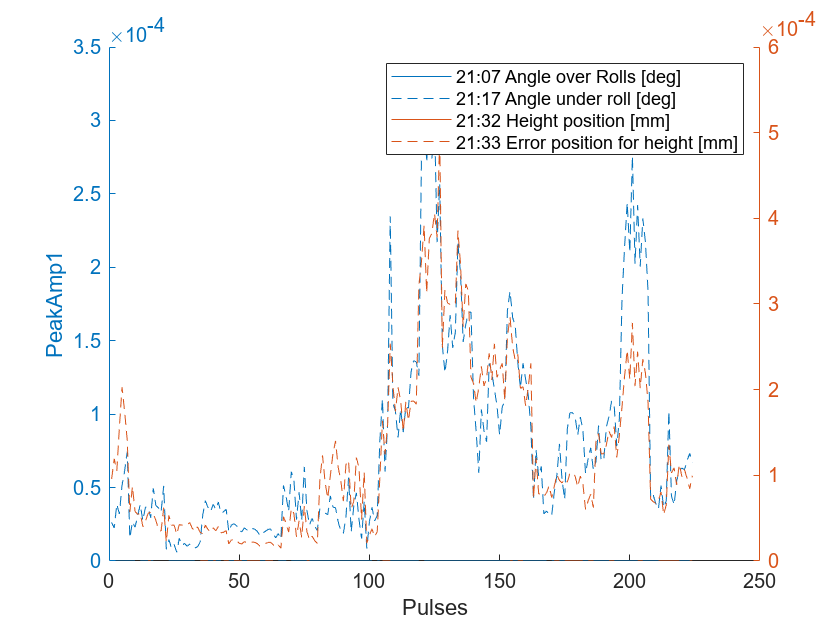

figure(); hold on;
FeatureNames_Combined(selectedFeature);%title(FeatureNames_Combined(selectedFeature));
xlabel("Pulses");
ylabel(FeatureNames_Combined(selectedFeature));
secondaryAxisArrayIndex = [2 3];
for i = 1:numOfSelectedSignals
    if ismember(i, secondaryAxisArrayIndex)
        yyaxis right;
    else
        yyaxis left;
    end
    plot(selectedSignalData{i});
    leg{i} = char(sensorNames(selectedSignalArray(i)));
end
legend(leg);
if (saveFigures == true)
    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
        + "Signal" + selectedSignal;
    print(filename,'-depsc','-tiff');
end

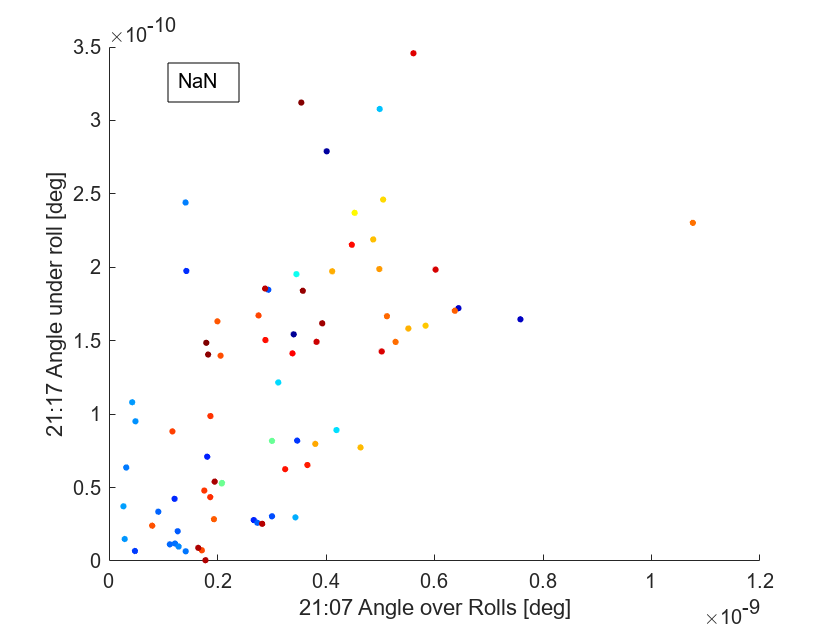

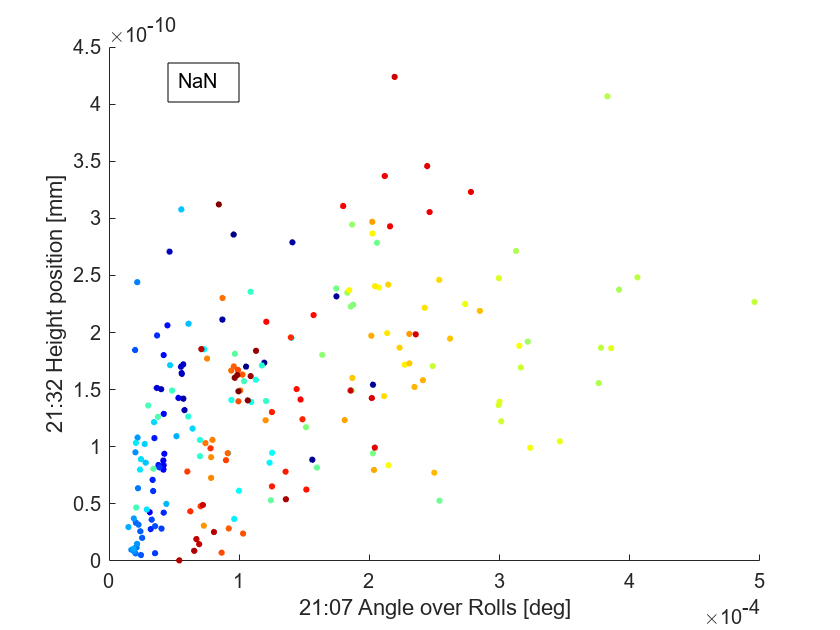

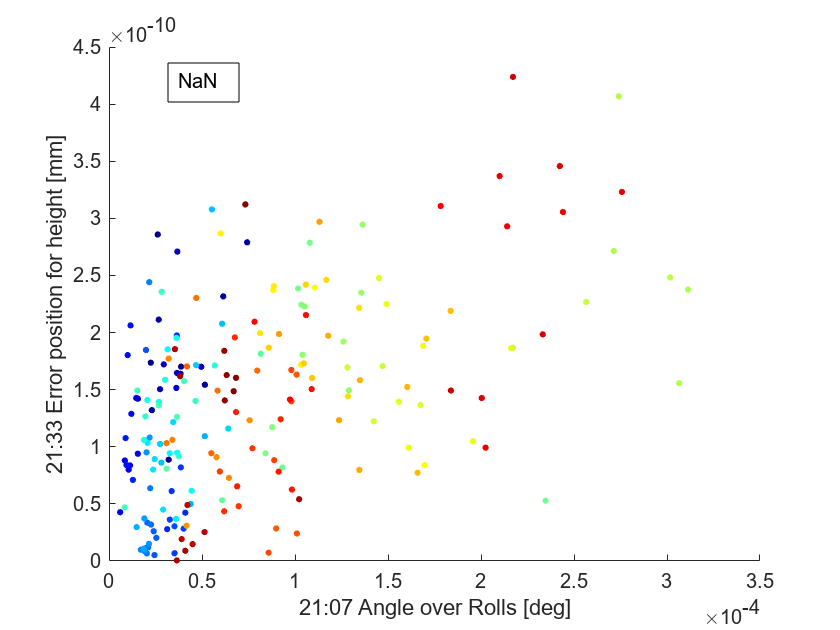

selectedSignalIdx = find(selectedSignalArray == selectedSignal);
linearModelNum = 1;
for index = 1 : numOfSelectedSignals
    if selectedSignalArray(index) ~= selectedSignal
        fnPlotModel(selectedSignalData{selectedSignalIdx}, ...
            selectedSignalData{index}, ...
            FeatureNames_Combined(selectedFeature), ...
            sensorNames(selectedSignalArray(index)), ...
            sensorNames(selectedSignal));
        if (saveFigures == true)
            filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                + "Signal" + selectedSignal ...
                + "_Linear" + linearModelNum;
            export_fig(filename, '-eps', '-depsc');
            linearModelNum = linearModelNum + 1;
        end
    end
end

PeakAmp1

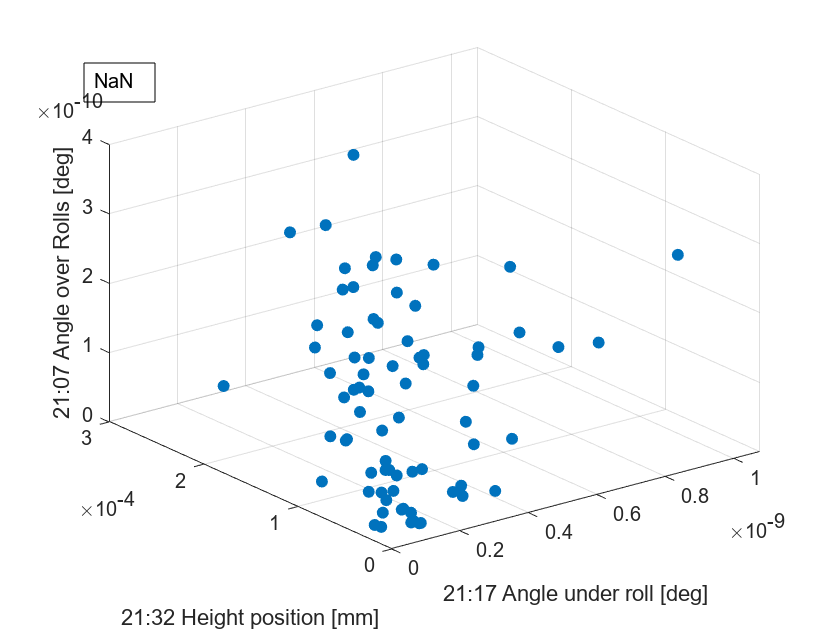

PeakAmp1

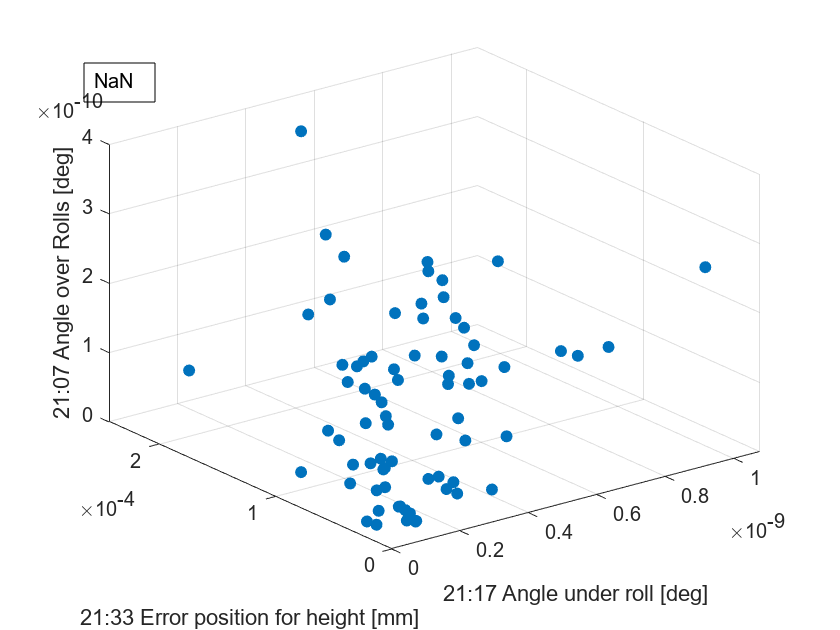

PeakAmp1

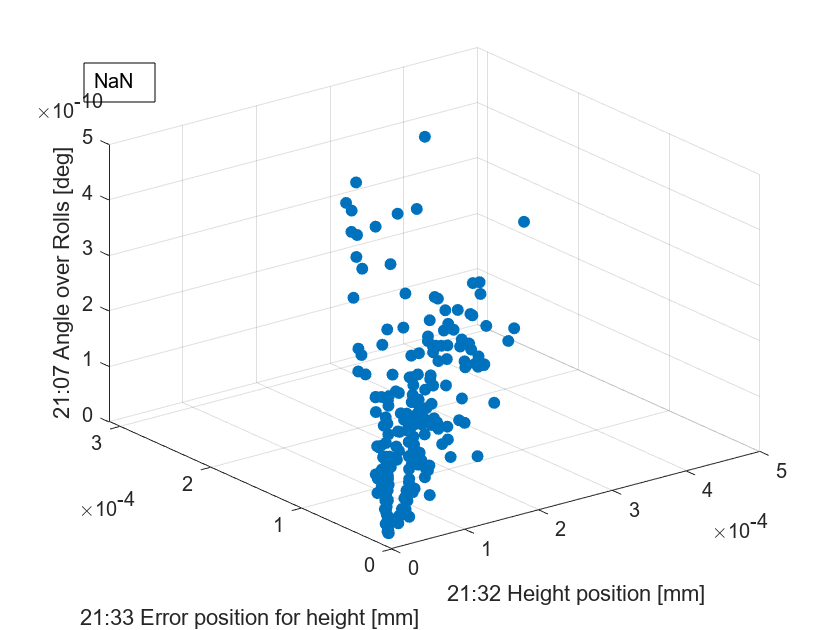

multivariateModelNum = 1;
if numOfSelectedSignals > 2
    for index1 = 1 : numOfSelectedSignals
        for index2 = index1+1 : numOfSelectedSignals
            if selectedSignalArray(index1) ~= selectedSignal && selectedSignalArray(index2) ~= selectedSignal 
                Y_est = fnPlotModel3D( ...
                    selectedSignalData{selectedSignalIdx}, ...
                    selectedSignalData{index1}, ...
                    selectedSignalData{index2}, ...
                    FeatureNames_Combined(selectedFeature), ...
                    sensorNames(selectedSignalArray(selectedSignalIdx)), ...
                    sensorNames(selectedSignalArray(index1)), ...
                    sensorNames(selectedSignalArray(index2)));
                if (saveFigures == true)
                    filename = "..\Latex Document\figures\Models_Feature" + selectedFeature ...
                        + "Signal" + selectedSignal ...
                        + "_Multivariate" + multivariateModelNum;
                    export_fig(filename, '-eps', '-depsc');
                    multivariateModelNum = multivariateModelNum + 1;
                end
            end
        end
    end
end